clc
clear all
close all

robot_name = '4R';
model = 'linear';
modality = '3D';
robot_path = strcat('saved_models/',robot_name,'/',model,'/',modality,'/matlab_files/');
addpath(robot_path)
addpath("paths/")
addpath("models/")
addpath("dynamics/robot_models/")

robot = robot_selector(robot_name, modality)

robot =   rigidBodyTree with properties:

     NumBodies: 5
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_1'  'link_2'  'link_3'  'link_4'  'link_ee'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


% load neural maps
forward_map_data = load("forward_map.mat")

forward_map_data = struct with fields:
        map_in_weights: [20×4 single]
           map_in_bias: [0.8946 -0.2216 0.3198 0.0281 0.3070 -0.6827 -0.0358 -0.8924 -0.6042 -0.5774 0.2615 0.3013 0.3446 -0.0484 -1.0675 0.4352 0.6575 -0.3430 0.1425 -0.5748]
      map_hidden_depth: 3
    map_hidden_weights: [20×20×3 double]
       map_hidden_bias: [1×20×3 double]
       map_out_weights: [3×20 single]
          map_out_bias: [0.1395 -0.0381 -0.0774]


encoder_data = load("encoder.mat")

encoder_data = struct with fields:
        encoder_in_weights: [30×8 single]
           encoder_in_bias: [-0.0073 2.5514e-04 0.0852 -0.0041 -0.1155 -0.1642 0.0076 -0.0458 -0.0033 0.2086 -0.0101 1.3819e-04 1.3480e-04 -0.1700 0.0572 -2.0661e-05 -0.0196 1.9030e-04 -0.0010 -0.0010 -0.0574 3.2442e-05 -8.3778e-04 2.7100e-04 0.0479 … ]
      encoder_hidden_depth: 2
    encoder_hidden_weights: [30×30×2 double]
       encoder_hidden_bias: [1×30×2 double]
       encoder_out_weights: [20×30 single]
          encoder_out_bias: [0.0787 0.0963 0.1247 -0.0808 -0.0012 -0.0426 0.0180 0.0205 0.1647 -0.0718 0.0273 0.1117 -0.1064 0.0841 -0.0205 -0.0687 0.0116 -0.0150 -0.0889 -0.0642]



load("dyn_mat.mat")
load("std.mat")

%discrete time parameters
Ad = A;
Bd = B;

%continuous time parameters
delT = 0.005;
N = size(A,1); %lifted dimension
m= length(robot.gravityTorque); %number of controls
Ac = (A-eye(N))/delT;
Bc = B/delT;
Cc = C;
Cc_red = C(1:m,:);

%ZNN IMPLEMENTATION
shape = "epicycloid"

shape = "epicycloid"

if strcmp(modality, '3D')
    num_states_cart = 3;
elseif strcmp(modality, '2D')
    num_states_cart = 2;
end
c = 0.02;
T = 10;
n=1;
iterations = T/delT;
t_span = 0:delT:T;
lambda= diag([100,100,100,300,300,300]);

u_plus_og = 1*ones(m,1);
if standardize == 1
    u_plus = (u_plus_og - mean')./scale';
end
u_minus = -u_plus;
phi = diag(u_plus-u_minus);
u(:,1) = 0*ones(m,1);

chi(:,1) = log((u(:,1)-u_minus)./(u_plus-u(:,1)));

t_start = cputime

t_start = 2.5165e+03

t_fnc = 0;

%inverse map for cardioid pat
if strcmp(robot_name,'3R')
    theta_traced(:,1) = [pi/4;pi/4;-pi/4];
elseif strcmp(robot_name,'4R')
    theta_traced(:,1) = [pi/4;pi/4;-pi/4; pi/4];
elseif strcmp(robot_name,'5R')
    theta_traced(:,1) = [pi/4;pi/4;-pi/4; -pi/4; pi/4];  
end

hom_tf = getTransform(robot,theta_traced(:,1),'link_ee');
if strcmp(modality,'2D')
    x_actual_traced(:,1) = hom_tf(1:num_states_cart,4);
    [dummy,xd_dot(:,1),xd_ddot(:,1)] = path_2D(c,0, x_actual_traced(:,1),0, T, shape);
    
       
else
    x_actual_traced(:,1) = hom_tf(1:num_states_cart,4);
    [dummy,xd_dot(:,1),xd_ddot(:,1)] = path_3D(c,0, x_actual_traced(:,1),0, T, shape);
    
end
x_traced(:,1) = x_actual_traced(:,1);
x_desired(:,1) = x_traced(:,1); %initial position of the end-effector same as desired position
x_traced_dot(:,1) = xd_dot(:,1);
theta_desired(:,1) = theta_traced(:,1);

W = neural_jacobian(theta_traced(:,1), forward_map_data);
theta_dot_desired(:,1) = pinv(W)*xd_dot(:,1);
theta_dot_traced(:,1) = theta_dot_desired(:,1);

%lifting
states_traced(:,1) = [theta_traced(:,1);   % states consists of theta and theta_dot
                      theta_dot_traced(:,1)];

z = lifting(states_traced(:,1),encoder_data);
z_dot(:,1) = Ac*z(:,1)+Bc*u(:,1);

for i=1:iterations
    t = t_span(i);
    if strcmp(modality,'2D')
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = path_2D(c,pi/6, x_traced(:,1),t, T, shape);
    else
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = path_3D(c,pi/6, x_traced(:,1),t, T, shape);
    end
     
    error(:,i) = [x_traced(:,i); x_traced_dot(:,i)] - [x_desired(:,i); xd_dot(:,i)];

    %Jacobian parameters
    W = neural_jacobian(theta_traced(:,i),forward_map_data);
    W_dot = neural_jacobian_dot(theta_traced(:,i),theta_dot_traced(:,i),forward_map_data);
    
    J_tilde = [W zeros(size(W));
                W_dot W];

    psi = diag(exp(chi(:,i))./(1+exp(chi(:,i))).^2);

    
    z_dot(:,i)=Ac*z(:,i)+Bc*u(:,i);

    chi_dot = pinv(Bd*phi*psi)*(-Ad*z_dot(:,i) + pinv(J_tilde*Cc)*([xd_dot(:,i);xd_ddot(:,i)] - lambda*error(:,i)));


    if i<=3
        chi(:,i+1) = chi(:,i)+chi_dot*delT;
    % elseif i>2 && i<=3
    %     chi(:,i+1) = (2*delT*chi_dot+4*chi(:,i)-chi(:,i-1))/3;
    % elseif i>3
    %     chi(:,i+1) = (12*delT*chi_dot+36*chi(:,i)-4*chi(:,i-2))/32;
    % 
    %  end

    else %FIFD
        chi(:,i+1) = (8/5)*chi_dot*delT + (3/5)*chi(:,i) + (1/5)*chi(:,i-1)+ (1/5)*chi(:,i-2); %FIFD
    end

    u(:,i+1) = phi*(exp(chi(:,i+1))./(1+exp(chi(:,i+1))))+u_minus;
    
    if standardize == 1
        u(:,i) = (u(:,i).*scale') + mean';
    end
    
     t_start_fnc = cputime;
     th_ddot = forwardDynamics(robot,theta_traced(:,i),theta_dot_traced(:,i),u(:,i));
     t_end_fnc = cputime;
     
     theta_dot_traced(:,i+1) = theta_dot_traced(:,i) + th_ddot*delT;
     theta_traced(:,i+1) = theta_traced(:,i) + theta_dot_traced(:,i+1)*delT;

     % [theta_traced(:,i+1), theta_dot_traced(:,i+1)] = dynamics_3R(u(:,i),theta_traced(:,i),theta_dot_traced(:,i));
     states_traced(:,i+1) = [theta_traced(:,i+1);theta_dot_traced(:,i+1)];
     z(:,i+1) = lifting(states_traced(:,i+1),encoder_data);
     
     x_traced(:,i+1) = neural_forward_map(theta_traced(:,i+1),forward_map_data);
     x_traced_dot(:,i+1) = neural_jacobian(theta_traced(:,i+1),forward_map_data)*theta_dot_traced(:,i+1);
     hom_tf = getTransform(robot,theta_traced(:,i+1),'link_ee');
     x_actual_traced(:,i+1) = hom_tf(1:num_states_cart,4);
    
     t_fnc = t_fnc+(t_end_fnc-t_start_fnc);
     % x_actual_traced(:,i+1) = forward_map_3R_real(theta_traced(:,i+1));
end

t_end = cputime;
comp_time = ((t_end-t_start)-t_fnc)/iterations;

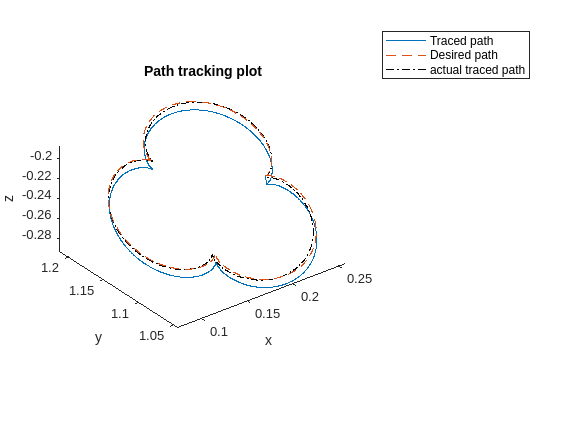

figure()
if strcmp(modality, '3D')
    plot3(x_traced(1,:),x_traced(2,:),x_traced(3,:))
    hold on
    plot3(x_desired(1,:),x_desired(2,:),x_desired(3,:),"--")
    hold on
    plot3(x_actual_traced(1,:), x_actual_traced(2,:),x_actual_traced(3,:),"k-.")
    xlabel("x")
    ylabel("y")
    zlabel("z")
    title("Path tracking plot")
    legend("Traced path","Desired path", "actual traced path")
    axis("equal")
    hold off
elseif strcmp(modality, '2D')
    plot(x_traced(1,:),x_traced(2,:))
    hold on
    plot(x_desired(1,:),x_desired(2,:),"--")
    hold on
    plot(x_actual_traced(1,:), x_actual_traced(2,:),"k-.")
    xlabel("x")
    ylabel("y")
    title("Path tracking plot")
    legend("Traced path","Desired path", "actual traced path")
    axis("equal")
    hold off

end

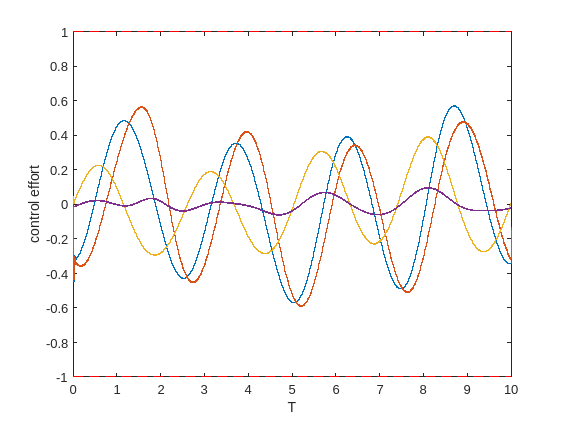

%plots
%control effort plot
figure()
for i = 1:m
 stairs(t_span(1:end),u(i,:))
 hold on
end
plot([0,T],[u_plus_og(1),u_plus_og(1)], 'r--' ,[0,T],[-u_plus_og(1),-u_plus_og(1)],'r--')
hold on
xlabel("T")
ylabel('control effort')
hold off

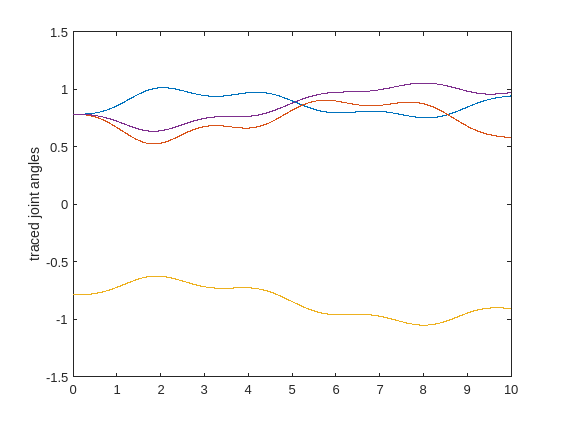

%states traced plot
figure()
for i  = 1:m
    plot(t_span,states_traced(i,:))
    hold on
end

ylabel('traced joint angles')
hold off

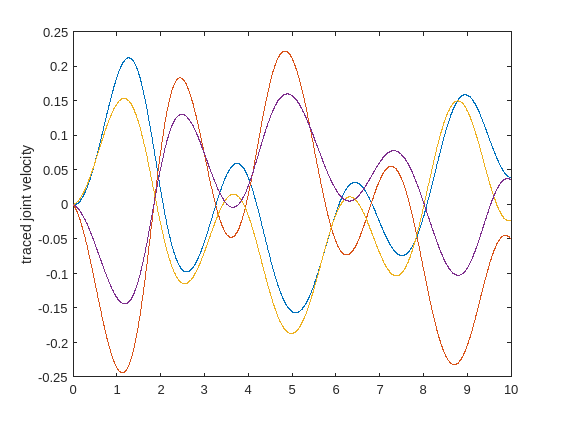

figure()
for i  = 1:m
    plot(t_span,states_traced(m+i,:))
    hold on
end

ylabel('traced joint velocity')
hold off

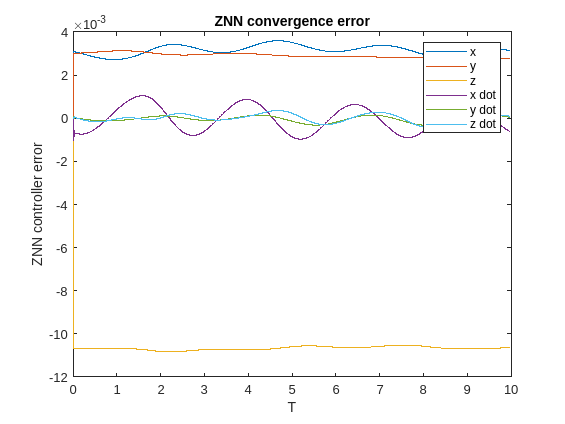

figure()
%error plot
plot(t_span(1:end-1),error)
xlabel('T')
ylabel("ZNN controller error")
legend("x","y", "z","x dot","y dot", "z dot")
title("ZNN convergence error")

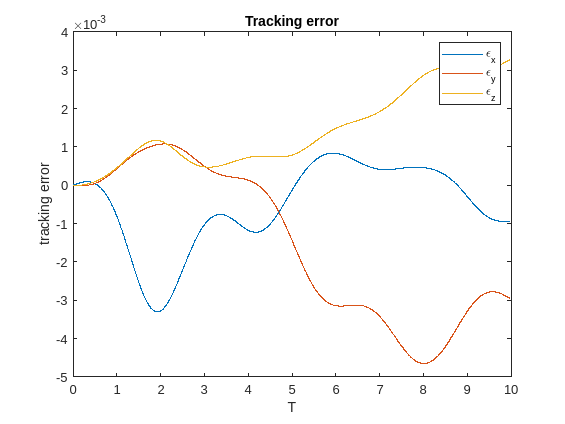

figure()
%error plot
tracking_error = x_desired-x_actual_traced(:,1:end-1);
plot(t_span(1:end-1),tracking_error)
xlabel('T')
ylabel("tracking error")
title("Tracking error")
legend("\epsilon_x","\epsilon_y","\epsilon_z")
hold off

%control effort required
u_norm = sum(vecnorm(u)*delT)

u_norm = 4.9467

%tracking error norm
tracking_error_norm = sum(vecnorm(x_desired-x_actual_traced(:,1:end-1))*delT)/T

tracking_error_norm = 0.0029

%tracking error norm
controller_error_norm = sum(vecnorm(error)*delT)/T

controller_error_norm = 0.0115